# 最小生成树

a = zeros(6)

a =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



% 注意，最小生成树是针对无向图的，每条边权重只需要设一次，1到2和2到1是同一条边
% 因此，可仅使用邻接矩阵的上三角矩阵来构造图G
a(1, [2 3]) = [14 18];  % 顶点1到其他顶点的边的权重
a(2, [3:5]) = [13 18 16];   % 顶点2到顶点3，顶点4，顶点5的边的权重
a(3, [4 5]) = [12 16];  % 同上，因为写过1到3，和2到3的边的权重，无需重复设置
a(4, [5 6]) = [14 19];
a(5, 6) = 10;

s = cellstr(strcat('城市',int2str([1:6]')));
G = graph(a, s, 'upper');
p = plot(G, 'EdgeLabel', G.Edges.Weight);

T = minspantree(G, 'Method','sparse');  % 可指定使用Kruskal算法

L = sum(T.Edges.Weight) % 对最小生成树的边的权重求和

L = 63

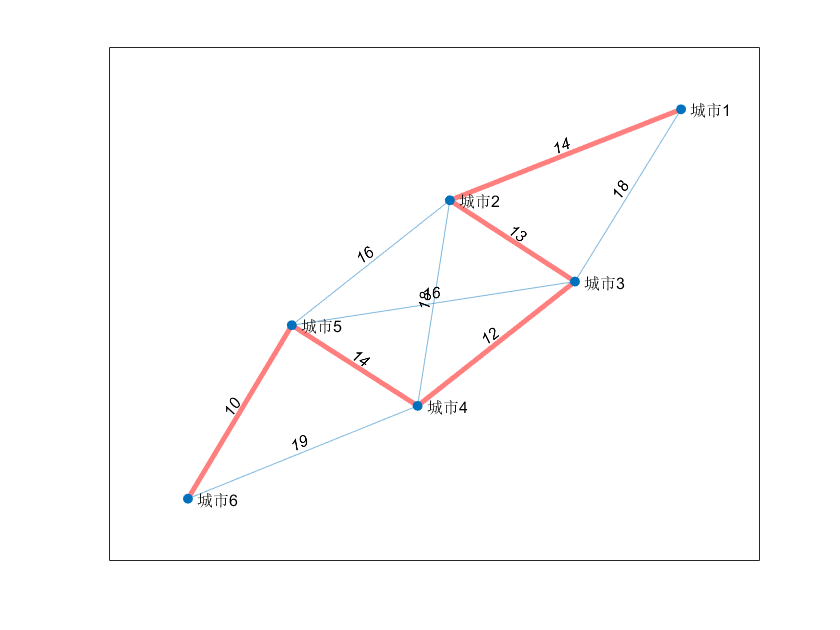

highlight(p,T,"EdgeColor","red","LineWidth",2.5)